# **Electromagnetism and the Yee Algorithm (PHY5017 Fall 2022)**

## **Team Remix: Joe Evans, Maxine Khumalo, Lang Liu**

This code is built-on and modified from research work that J. Evans did in the Fall of 2020.

## Version Comments

Propogation:

This is the same propogation code as Yee_v10, except that the gaussian is fed in as a pulse over time as defined in part 3 of the project.     This version propogates the wave in the same manner as v10 did, but the wave is made up of a superpostion of waves caused by the pulse.  

Reflection:

The left boundary gives a bounce back with noise.  The right boundary gives a more exotic combination of a  bounce back and reflection that is really quite beautiful.  I believe the difference between the two sides has to do with the fact that we have different boundaries on the left and right.  On the left, we hold E(0) = 0 & H(0) = 0.  However, on the right, we sometimes hold two zeros for the last two values of E and H, but not always.  This was for utility to make the code work.  However, the calculations obviously get messed up in exotic ways at these boundaries. Also, there is a secondary reflection at L/4 because of the Guassian function that overwrites the value at that point.  

## Admin

clearvars
sympref('FloatingPointOutput',true);

## Section 1: Define Constants and Courant Number

### Given Constants

e0 = 8.86e-12; %permittivity of free space (F/m)

mu0 = 4e-7 .* pi; % permeability of free space (H/m)

er = 1; %permittivity in medium (set to 1 for free space)

mur = 1; %permeability in medium (set to 1 for free space)

e = er .* e0; % e = epsilon (Units F/m)

mu = mur .* mu0; % (Units: H/m)

c = 1./(sqrt(e0*mu0));

### Set Courant number (S)

Set $S=\frac{c \Delta t}{\Delta z}$

Then $\Delta t = S\frac{\Delta z}{c}$

S = 1; %Courant Number of 1/2 corresponds to the magic time step

c = 3e8; % speed of light in (meters / second)

dz = 5e-3; %space increment in meters as defined in the project part 3 parameters

dt = S .* (dz./c) ;


## Section 2: Set up the Wave

### Gaussian Pulse in Time "Wave Packet"

sigma = 8 .* dt;  %as defined in Project Part 3

ts = 20 .* dt;

E0 = 1;

Es = @(t) E0 .* exp(-((t-ts)^2)./(sigma^2));

Z=(dz/2):(dz):1    %for plotting and video purposes

Z =     0.0025    0.0075    0.0125    0.0175    0.0225    0.0275    0.0325    0.0375    0.0425    0.0475    0.0525    0.0575    0.0625    0.0675    0.0725    0.0775    0.0825    0.0875    0.0925    0.0975    0.1025    0.1075    0.1125    0.1175    0.1225    0.1275    0.1325    0.1375    0.1425    0.1475    0.1525    0.1575    0.1625    0.1675    0.1725    0.1775    0.1825    0.1875    0.1925    0.1975    0.2025    0.2075    0.2125    0.2175    0.2225    0.2275    0.2325    0.2375    0.2425    0.2475


### Create Matrices to hold wave values



L = 1./dz;               %Number of Space Positions so that z(L) = 1

Tmax = 6 .* sigma;          
T = Tmax ./ dt;           %Number of Time Steps so that over 99% of the Guassian pulse is complete

%Matrices to hold E and H values will be row vectors of length 2L, so that
%each position represents a half step.  

E = zeros(1,L);          %Matrix of electric field values in space (@ t)
Ein = zeros(1,L);        %Temporary Placeholder for the E value input for each space step
Eout = zeros(1,L);       %Temproary placeholder for the E value output for each space step

H = zeros (1,L-1);         %Matrix of magnetic field values in space (@ t)
Hin = zeros(1,L-1);        %Temporary placeholder for the H value input for each space step
Hout = zeros (1,L-1);      %Temporary placeholder for the H value output for each space step

zs = L./4;                  %Define the space point of the Gaussian pulse


### Guassian in Space

This is a Guassian in space for the E field, which can be introduced in lieu of a Guassian pulse in time for testing purposes 

 
%   a = 1;     %height
%   b = 1/4;    %center
%   d = 8*dz;    %width
%   f=@(x)a*exp(-((x-b).^2)/(d^2));
%   E(:)=f(Z);
%  


### Square Wave in Space

This is a Square wave in space for the E field, which can be introduced in lieu of a Gaussian pulse in time for testing purposes

% E(50:150)=1;

## Section 3: Setup Video

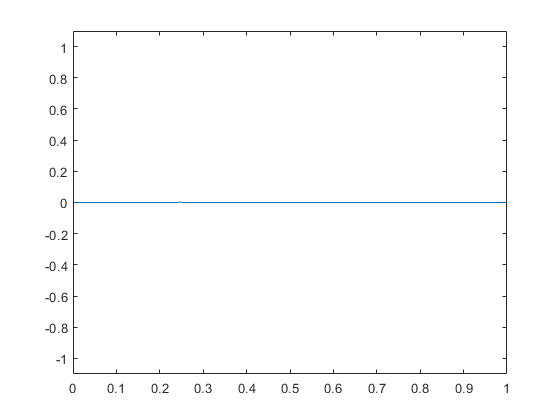

v=VideoWriter("Wave4","MPEG-4");
open(v)
plot(Z,E(:))
xlim([0 1]);
ylim([-1.1 1.1]);
Ylabel="Amplitude";
Xlabel="z";
axis manual
set(gca,"nextplot","replacechildren")
frame=getframe(gcf);

writeVideo(v,frame)


## Section 5: Absorbing Boundary Conditions

This is an implementation of Part 4.6

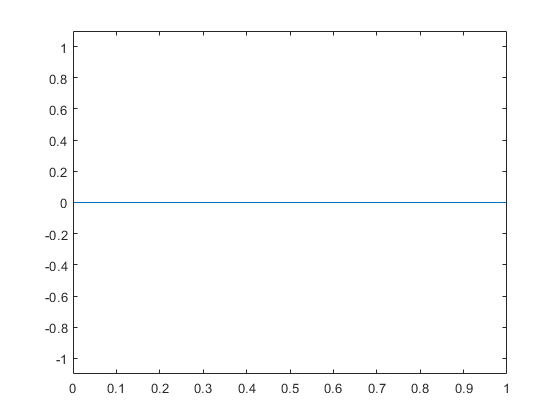


for t=1:8*T                              %Iterate for T total time steps
    L = round(L);
    
%%%%%%%%%%%%%%%%%%%%% Calculate the E Field %%%%%%%%%%%%%%%%%%%

    E2_old = E(2);                                % ABCs
    EM1_old = E(L-1);
    
    for k=2:(L-1)                     
        Hout(k) = H(k);
        Hin(k)= H(k-1);
    end   
    
    for k=2:(L-1)
        E(k) =  E(k) - ( S ./ er )  .* ( Hout(k) - Hin(k) );    %calculate E 
    end
    
    E2_new = E(2);                                % ABCs
    E(1) = E2_old + (S - sqrt(er*mur)) ./ (S + sqrt(er*mur)) .* (E2_new - E(1));
    EM1_new = E(L-1);
    E(L) = EM1_old + (S - sqrt(er*mur)) ./ (S + sqrt(er*mur)) .* (EM1_new - E(L));
    
%%%%%%%%%%%%%%%%%%% Introduce next E pulse Value %%%%%%%%%%%%%%%%%%

                      
    E(zs) = Es(t*dt); %Calculate the next value of the pulse at z = zs 

   
   
%%%%%%%%%%%%%%%%%% Calculate H Field %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
    for k=1:(L-1)                       
        Eout(k) = E(k+1);
        Ein(k) = E(k);                % these values are populated with E @ t+(1/2)  
    end
    
    for k=1:(L-1) 
        H(k) = H(k) - (S ./ mur ) .* ( Eout(k) - Ein(k) );   %calculate H
    end
    
%%%%%%%%%%%%%%%%% Plot and Write frame to video %%%%%%%%%%%%%%%%%%%%

    plot(Z,E(:));
    frame=getframe(gcf);
    pause(0.5)
    writeVideo(v,frame)
    
end

close(v)